# Residual Supply Index estimation of selected market participants

## Import the list of selected generators

load cleanedQMCTables.mat

## Import selected datetime and price

load selDateTimePriceISONE.mat;
selDateTimes = selDateTimePrice.DateTime;
selDates = selDateTimePrice.Date;
selHours = selDateTimePrice.Hour;
numSelDateTimes = size(selDateTimes, 1);

## Import ISONE hourly demand data

% Import ISONE hourly demand data in the 2019 whole year
% Run this under the model_code directory or change the genFileDir manually
demandFileDir = "..\data\2019_DEMAND_ISONE\";
demandFileName = "da_hourlydemand_2019*.csv";
demandDataStore = fileDatastore(demandFileDir + demandFileName, "ReadFcn", @importDemandISONE, "UniformRead", true);
demandAll = readall(demandDataStore);
clear demandDataStore;

## Import generation capacity and Lerner Index data

load partCapTable.mat
load LernerPolyfitResults.mat

partCapTable

partCapTable = 87×3 table
    PartID    Capacity    OtherCap
    ______    ________    ________

    124454         93      32176  
    126216     1126.8      31142  
    172669       57.5      32212  
    173252      248.5      32021  
    184983         14      32255  
    188321         32      32237  
    196063        433      31836  
    206845     2513.5      29756  
    20721        44.5      32225  
    212494       1927      30342  
    219842        680      31589  
    292445      571.9      31697  
    295534        591      31678  
    331313      131.5      32138  
    355376         80      32189  
    364108        7.7      32262  


partCap = zeros(numParts, 1);
partIDs = categorical(partIDs);
partOtherCap = zeros(numSelParts, 1);
for n=1:numParts
    partCap(n) = partCapTable(partCapTable.PartID == partIDs(n), :).Capacity;
    partOtherCap(n) = partCapTable(partCapTable.PartID == partIDs(n), :).OtherCap;
end

## Calculate market share and residual supply index

MS = zeros(numParts, numSelDateTimes); % Market share
RSI = zeros(numParts, numSelDateTimes); % Residual supply index
for dt=1:numSelDateTimes
    selDate = selDates(dt);
    selHour = selHours(dt);
    % Obtain total demand at the selected hour
    hourlyDemand = demandAll(demandAll.Date == selDate, :);    
    selHourDemand = hourlyDemand(hourlyDemand.Hour == selHour, :).DayAheadDemand;
    for n=1:numParts
        % Calcualte market share
        MS(n, dt) = min(partCap(n), selHourDemand)/selHourDemand;
        % Calculate residual supply index
        RSI(n, dt) = partOtherCap(n)/selHourDemand;
    end    
end

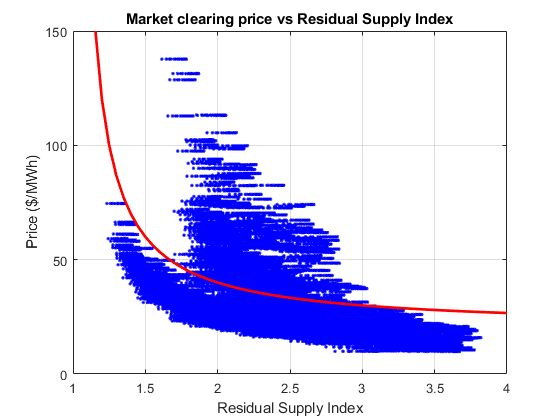

priceArray = selDateTimePrice.averageLMP;
RSIArray = 1:0.05:4;
priceUpper = (RSIArray./(RSIArray-1))*20;
figure;
hold on;
for n=1:numParts
    scatter(RSI(n, :), priceArray', "b.");
end
plot(RSIArray, priceUpper, 'r-', "LineWidth",2);
hold off; box on; grid on;
axis([1, 4, 0, 150]);
xlabel("Residual Supply Index");
ylabel("Price ($/MWh)");
title("Market clearing price vs Residual Supply Index");

## Calculate Lerner index upper bound and price upper bound using selected market participants' data

selPartIdx = ismember(partIDs, selPartIDs);
selPartCap = partCap(selPartIdx);
selPartOtherCap = partOtherCap(selPartIdx);
selMSRSITables = cell(numSelParts, 1);
for n=1:numSelParts
    selLernerTable = selLernerFitTables{n};
    cleanedDates = selLernerTable.Date;
    cleanedHours = selLernerTable.Hour;
    numCleanedDateTimes = size(cleanedHours, 1);
    selMS = zeros(numCleanedDateTimes, 1);
    selRSI = zeros(numCleanedDateTimes, 1);
    selLIUpper = zeros(numCleanedDateTimes, 1);
    selPriceUpper = zeros(numCleanedDateTimes, 1);
    selMC = selLernerTable.MCMarket;
    selLI = selLernerTable.LernerData;
    selPrice = selLernerTable.averageLMP;
    for dt=1:numCleanedDateTimes
        Date = cleanedDates(dt);
        Hour = cleanedHours(dt);
        hourlyDemand = demandAll(demandAll.Date == Date, :);    
        selHourDemand = hourlyDemand(hourlyDemand.Hour == Hour, :).DayAheadDemand;
        % Calcualte market share
        selMS(dt) = min(selPartCap(n), selHourDemand)/selHourDemand;
        % Calculate residual supply index
        selRSI(dt) = selPartOtherCap(n)/selHourDemand;
        % Calculate Lerner Index upper bound
        selLIUpper(dt) = selMS(dt)/(selMS(dt) + selRSI(dt) - 1);
        % Calculate price upper bound
        selPriceUpper(dt) = (1 + (selMS(dt)/(selRSI(dt) - 1)))*selMC(dt);
    end
    selMSRSITables{n} = table(cleanedDates, cleanedHours, selMC, selMS, selRSI, selLI, selLIUpper, selPrice, selPriceUpper);
    selMSRSITables{n}.Properties.VariableNames = ["Date", "Hour", "MC", "MS", "RSI", "LI", "LIUpper", "Price", "PriceUpper"];
end

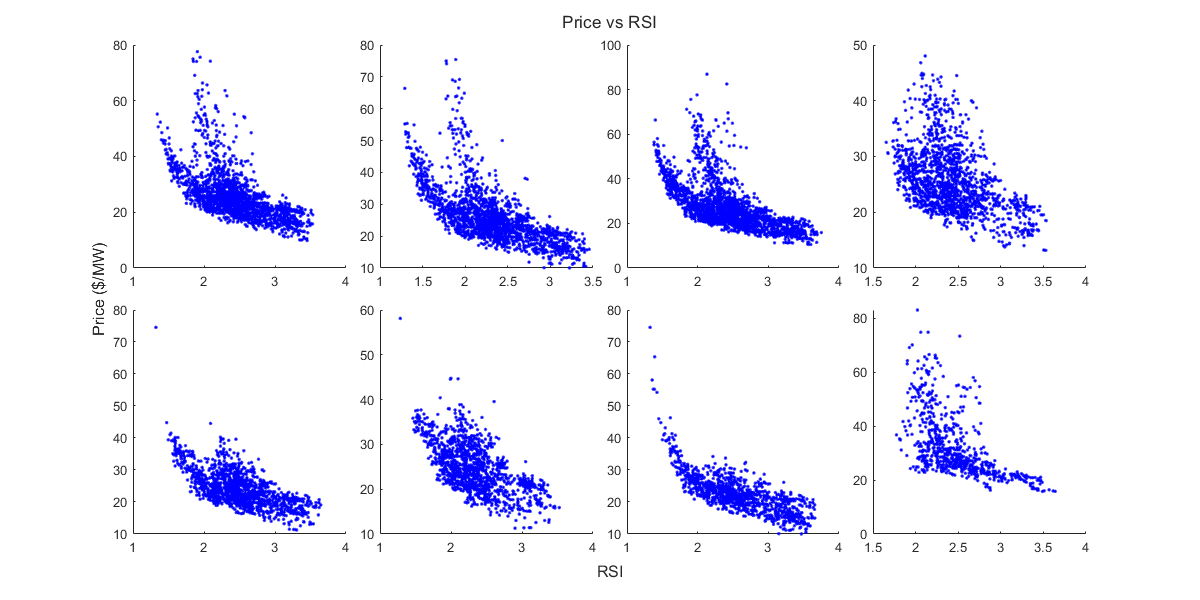

figure;
plotColumn = 4;
t = tiledlayout(numSelParts/plotColumn, plotColumn, "TileSpacing","compact");
for n=1:numSelParts
    nexttile;
    selTable = selMSRSITables{n};
    scatter(selTable.RSI, selTable.Price, 'b.');
%     hold on;
%     scatter(selTable.RSI, selTable.PriceUpper, 'r.');
%     hold off;
end
xlabel(t, "RSI");
ylabel(t, "Price ($/MW)");
title(t, "Price vs RSI");
set(gcf, "Position", [50, 50, 1200, 600]);

% saveas(gcf, "../model_output/figures/MCCubicPolyfit.png");

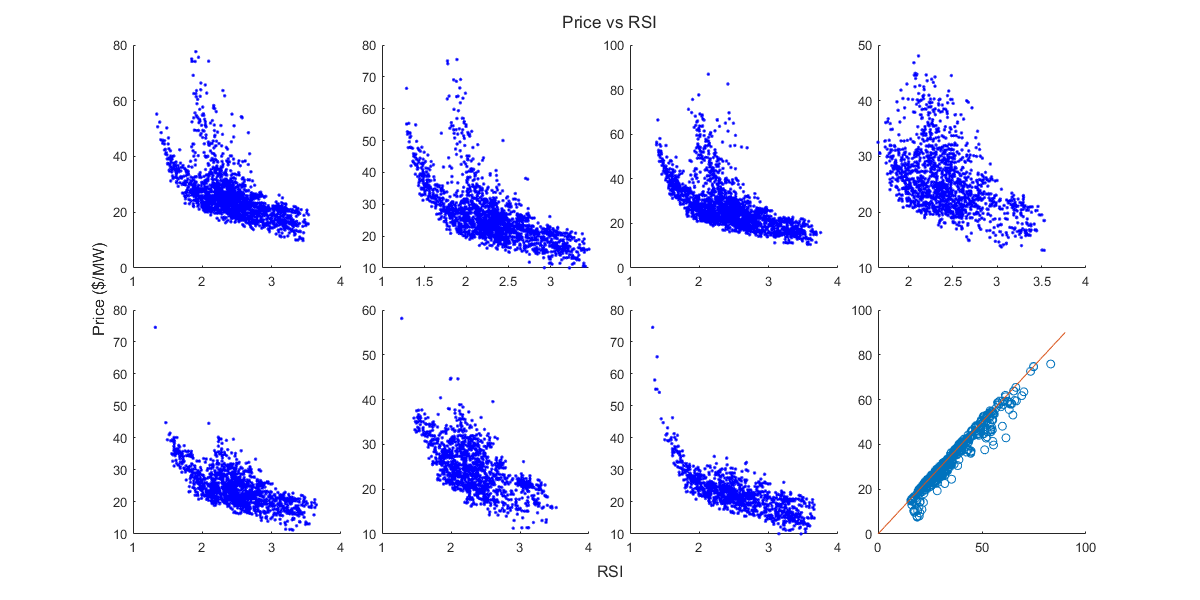

selTable = selMSRSITables{n};
figure;
scatter(selTable.Price, selTable.PriceUpper);
hold on;
plot(0:90, 0:90);
hold off;

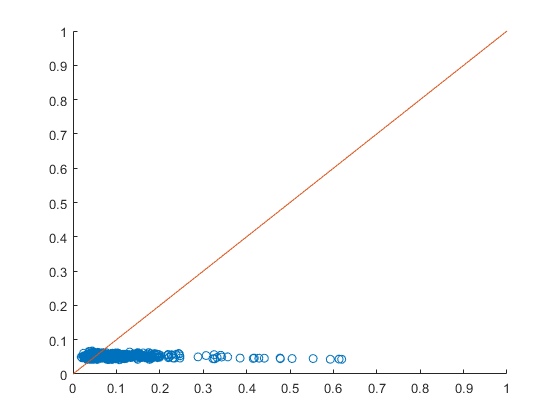

selTable = selMSRSITables{n};
figure;
scatter(selTable.LI, selTable.LIUpper);
hold on;
plot(0:1, 0:1);
hold off;